# CS 71 Lab 1

Jessie Li

September 20, 2023

## Part A

% Source: https://www.mathworks.com/help/matlab/ref/besselj.html
x = [1 15 30];
n = 30;

% Calculate exact Bessel functions for n = 0 to 30 
% and evaluate at x = 1, 15, and 30
J = zeros(n+1, length(x));
for i = 0:n
    J(i+1, :) = besselj(i, x);
end

% Calculating Bessel functions in the forward direction
Jhat = bessel_forward(n, x)

Jhat = 1.0e+40 *

    0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000
    0.0000    0.0000    0.0000
    0.0000   -0.0000    0.0000
    0.0000   -0.0000   -0.0000
    0.0000    0.0000   -0.0000
    0.0000    0.0000   -0.0000
    0.0000    0.0000    0.0000
    0.0000   -0.0000    0.0000
    0.0000   -0.0000   -0.0000



writematrix(Jhat, 'Jhat.csv')

% Calculating absolute and relative errors
absolute_errors_forward = absolute_error(J, Jhat);
relative_errors_forward = relative_error(J, Jhat);

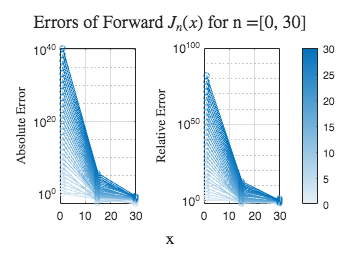

% Graphing errors as a function of x
t = tiledlayout(1, 2);

c = sky(31); % colormap
colormap sky
colororder(c);

% Absolute errors
ax1 = nexttile;
plot(x, absolute_errors_forward, '-o', 'MarkerSize', 4);
ylabel(ax1, 'Absolute Error', 'interpreter', 'latex');
grid on

% Relative errors
ax2 = nexttile;
plot(x, relative_errors_forward, '-o', 'MarkerSize', 4);
ylabel(ax2, 'Relative Error', 'interpreter', 'latex');
grid on

% Add colorbar 
clim([0, 30]);
cb = colorbar(); 
cb.Layout.Tile = 'east';

% Add title, shared x label, and set y scale to log
title(t, 'Errors of Forward $J_n(x)$ for n =[0, 30]', 'interpreter','latex');
xlabel(t, 'x', 'interpreter', 'latex');
set([ax1, ax2], 'YScale', 'log');

% Save figure
saveas(gcf, 'partA-errors-x.png');

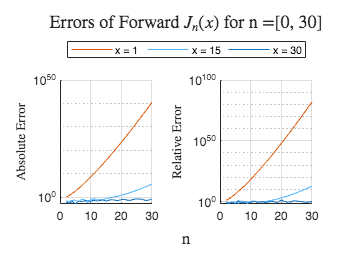

% Graphing errors as a function of n
t = tiledlayout(1, 2);

colororder('reef');

% Absolute errors
ax1 = nexttile;
ylabel(ax1, 'Absolute Error', 'interpreter', 'latex');
grid on

hold on
for i = 1:3 
    plot(ax1, 0:30, absolute_errors_forward(:, i));
end
hold off

% Relative errors
ax2 = nexttile;
ylabel(ax2, 'Relative Error', 'interpreter', 'latex');
grid on

hold on
for i = 1:3 
    plot(ax2, 0:30, relative_errors_forward(:, i));
end
hold off

% Add title, legend, shared n label, and set y scale to log
title(t, 'Errors of Forward $J_n(x)$ for n =[0, 30]', 'interpreter','latex');
xlabel(t, 'n', 'interpreter', 'latex');
set([ax1, ax2], 'YScale', 'log');

leg = legend('x = 1', 'x = 15', 'x = 30', 'Orientation', 'horizontal');
leg.Layout.Tile = 'north';

% Save figure
saveas(gcf, 'partA-errors-n.png');

## Part B

% Calculating Bessel functions in the backward direction
Jback = bessel_backward(n, x)

Jback =    26.3957    0.7655   -0.1432
    6.8923    0.1551    0.0800
    1.1735   -0.7241    0.1538
    0.1486   -0.4448   -0.0492
    0.0150    0.4869   -0.1670
    0.0013    0.7694   -0.0064
    0.0001    0.1286    0.1644
    0.0000   -0.6493    0.0831
    0.0000   -0.8212   -0.1201
    0.0000   -0.3361   -0.1552



writematrix(Jback, 'Jback.csv')

% Calculate errors
absolute_errors_backward = absolute_error(J, Jback);
relative_errors_backward = relative_error(J, Jback);

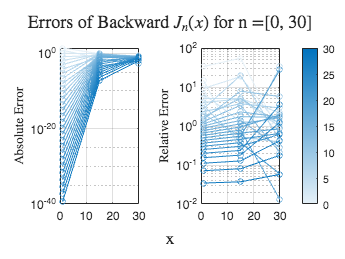

% Graphing errors as a function of x
t = tiledlayout(1, 2);

c = sky(31); % colormap
colormap sky
colororder(c);

% Absolute errors
ax1 = nexttile;
plot(x, absolute_errors_backward, '-o', 'MarkerSize', 4);
ylabel(ax1, 'Absolute Error', 'interpreter', 'latex');
grid on

% Relative errors
ax2 = nexttile;
plot(x, relative_errors_backward, '-o', 'MarkerSize', 4);
ylabel(ax2, 'Relative Error', 'interpreter', 'latex');
grid on

% Add colorbar 
clim([0, 30]);
cb = colorbar(); 
cb.Layout.Tile = 'east';

% Add title, shared x label, and set y scale to log
title(t, 'Errors of Backward $J_n(x)$ for n =[0, 30]', 'interpreter','latex');
xlabel(t, 'x', 'interpreter', 'latex');
set([ax1, ax2], 'YScale', 'log');

% Save figure
saveas(gcf, 'partB-errors-x.png');

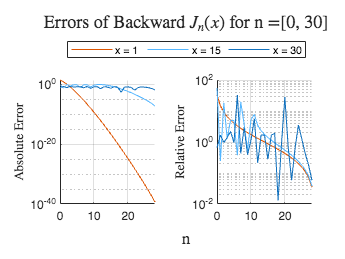

% Graphing errors as a function of n
t = tiledlayout(1, 2);

colororder('reef');

% Absolute errors
ax1 = nexttile;
ylabel(ax1, 'Absolute Error', 'interpreter', 'latex');
grid on

hold on
for i = 1:3 
    plot(ax1, 0:30, absolute_errors_backward(:, i));
end
hold off

% Relative errors
ax2 = nexttile;
ylabel(ax2, 'Relative Error', 'interpreter', 'latex');
grid on

hold on
for i = 1:3 
    plot(ax2, 0:30, relative_errors_backward(:, i));
end
hold off

% Add title, legend, shared n label, and set y scale to log
title(t, 'Errors of Backward $J_n(x)$ for n =[0, 30]', 'interpreter','latex');
xlabel(t, 'n', 'interpreter', 'latex');
set([ax1, ax2], 'YScale', 'log');

leg = legend('x = 1', 'x = 15', 'x = 30', 'Orientation', 'horizontal');
leg.Layout.Tile = 'north';

% Save figure
saveas(gcf, 'partB-errors-n.png');

## Functions

function J = bessel_forward(n, x)
    % Returns Bessel functions computed in the forward direction from 0 up
    % n evaluated at a given value of x
    J = zeros(n+1, length(x));

    J(1, :) = besselj(0, x); % J_0(x)
    J(2, :) = besselj(1, x); % J_1(x)

    for i = 2:n
        J(i+1, :) = (2*i ./ x) .* J(i, :) - J(i-1, :);
    end
end

function J = bessel_backward(n, x)
    % Returns Bessel functions computed in the backward direction from n down to 0
    % evaluated at a given value of x
    J = zeros(n+1, length(x));

    J(n+1, :) = besselj(n, x); % J_n(x)
    J(n, :) = besselj(n-1, x); % J_(n-1)(x)

    for i = n:-1:2
	    J(i-1, :) = (2*i ./ x) .* J(i, :) - J(i+1, :);
    end

end

function e = absolute_error(x, xhat)
    % Returns an array of absolute errors for each element in x
    e = abs(x - xhat); 
end

function e = relative_error(x, xhat)
    % Returns an array of relative errors for each element in x
    e = abs((x - xhat) ./ x);
end